# Example 118 Bus System - EMT

Copyright © 2025, The MathWorks, Inc.

## Introduction

There are two parts to this workflow. 

First, we will use [MATPOWER](https://github.com/MATPOWER/matpower) (a MATLAB Community Toolbox) to perform a load flow calculation of an example 118 bus system. A load flow is a fundamental calculation performed by power systems engineers, to calculate an operating point of an electric grid and connected assets. Load flow calculations use optimization to determine the power levels on generators and loads, as well as the voltage levels on the network buses (nodes).

Second, we will use the information from MATPOWER to build the network model of the example 118 bus system using Simscape™ Electrical™ for use in EMT simulation. The model is then connected to dynamic assets for subsequent dynamic simulation. 

Use MathWorks Release R2025b,

MATLAB®

Simulink®

Simscape™

Simscape™ Electrical™

MATPOWER 8.0 (MathWorks Community Toolbox)

Simscape Electrical Support Library for Power System Engineers

## Load Flow

The network data for the example 118 bus system is contained within the file case118.m in MATPOWER. The function loadcase in MATPOWER reads the case data into a data structure.

bdclose all
clear

data = loadcase('case118');

This system has 19 generators, 35 synchronous condensers, 118 buses (nodes), 175 branches (cables), and 101 loads.

Now we can calculate a basic load flow using the function runpf in MATPOWER. The results are stored to a new data structure.

data1 = runpf(data)


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 3 iterations.
PF successful

Converged in 0.43 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses            118     Total Gen Capacity    9966.2       -7345.0 to 11777.0
Generators        54     On-line Capacity      9966.2       -7345.0 to 11777.0
Committed Gens    54     Generation (actual)   4374.9             795.7
Loads             99     Load                  4242.0            1438.0
  Fixed           99       Fixed               4242.0            1438.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0      

data1 = struct with fields:
       version: '2'
       baseMVA: 100
           bus: [118×13 double]
           gen: [54×21 double]
        branch: [186×17 double]
       gencost: [54×7 double]
      bus_name: {118×1 cell}
         order: [1×1 struct]
          task: [1×1 mp.task_pf_legacy]
            et: 0.4288
       success: 1
    iterations: 3
            om: [1×1 mp.math_model_pf_acps]


Use a graph to display the network. 

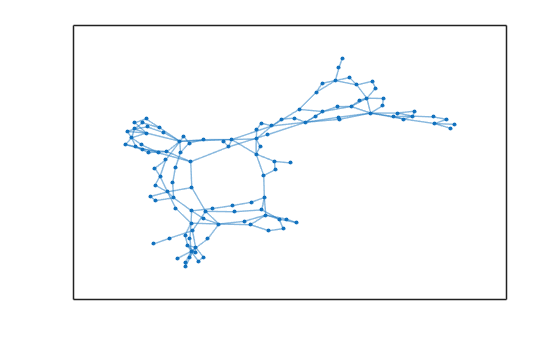

[X,Y] = displayGraph(data1);

## Additional Parameters for Model Build

Ts = 5e-5;

% from and to voltage levels on the branches
[~,idxf] = ismember(data1.branch(:,1),data1.bus(:,1));
[~,idxt] = ismember(data1.branch(:,2),data1.bus(:,1));
data1.fV = data1.bus(idxf,10);
data1.tV = data1.bus(idxt,10);
data1.X = X*800;
data1.Y = Y*800+1600;

freq = 60; % nominal (rated) frequency

genBus = unique(data1.gen(:,1));

idxLoad = data1.bus(:,3)~=0 | data1.bus(:,4)~=0 | data1.bus(:,6)~=0;
data1.busLoad = unique(data1.bus(idxLoad,1));
data1.busGenPV = data1.bus(data1.bus(:,2) == 2 | data1.bus(:,2) == 3,1);

ww = arrayfun(@num2str, unique(data1.bus(:,10)), 'UniformOutput', false);
voltageLevels = cellfun(@(x) strrep(x,'.','p'),ww,'UniformOutput',false);

## Build the EMT Model

Open the blank canvas

mdl = 'blank_canvas_118';
open_system(mdl)

Add the buses 

bus_placement(mdl,data1)
disp('buses done')

buses done


Add the branches. If the propogation delay of a given line is greater than the time step, then a Bergeron line model is used, otherwise a pi-section line is used.

branch_placement_bergeron(mdl,data1,freq,Ts)
disp('lines done')

lines done


Define inputs

tagI = define_inputs(mdl,voltageLevels);

Define outputs

define_outputs(mdl,voltageLevels)

Add the Simscape Solver Configuration block

% find the first bus
hb = find_system(mdl,'FindAll','on','Name',['node_',num2str(data1.bus(1,1))]);

% copy solver configuration over to model
hsc = add_block('nesl_utility/Solver Configuration',[mdl,'/Solver Configuration']);

% put solver configuration near the bus
psc = get(hsc,'Position');
pos = psc - [psc(1) psc(2) psc(1) psc(2)];
pb = get(hb,'Position');
set(hsc,'Position',pos + [pb(1)-150 pb(2)-50 pb(1)-150 pb(2)-50])

% get port handles
b1 = get(hb,'Porthandles');
b2 = get(hsc,'Porthandles');

% connect the solver configuration to the bus
add_line(mdl,b1.LConn(1),b2.RConn(1))

% configure the solver parameters for large-scale simulation
set(hsc,'EquationFormulation','NE_TIME_EF')
set(hsc,'IndexReductionMethod','None')
set(hsc,'ConsistencyTolSource','LOCAL')
set(hsc,'ConsistencyAbsTol','1e4')
set(hsc,'ConsistencyRelTol','1e4')
set(hsc,'ConsistencyTolFactor','1')
set(hsc,'UseLocalSolver','on')
set(hsc,'DoFixedCost','on')
set(hsc,'MaxNonlinIter','1')
set(hsc,'ResolveIndetEquations','off')
set(hsc,'LocalSolverChoice','NE_BACKWARD_EULER_ADVANCER')
set(hsc,'LocalSolverSampleTime','Ts')
set(hsc,'LinearAlgebra','Sparse')
set(hsc,'AutomaticFiltering','off')

Define Bus Signal Objects

warning('off','Simulink:utility:slUtilityCompBusCannotUseSignalNameForBusName')

clear slB*

mdl1 = 'busCreators01';

open_system(mdl1)

% delete the existing blocks
try
    delete_block([mdl1,'/measurements']);
catch
end

% Copy measurements subsystem from mdl to mdl1

hv1 = add_block([mdl,'/measurements'],[mdl1,'/measurements']);

hbc = find_system(mdl1,'FindAll','on','BlockType','BusCreator');
set(hbc,'OutDataTypeStr','Inherit: auto')

hop = find_system(mdl1,'FindAll','on','BlockType','Outport');
set(hop,'OutDataTypeStr','Inherit: auto')

for xx1 = 1:numel(voltageLevels)

    busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/bus_',voltageLevels{xx1},'kV_outputs/bus_',voltageLevels{xx1},'kV_output_bus']); %#ok<*NASGU>
    eval(['n_slBus',num2str(xx1),' = eval(busInfo1.busName);']); %#ok<*EVLSEQVAR>
    clear busInfo1

end


busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/line_current_outputs/line_current_output_bus']);
eval(['n_slBus',num2str(xx1+1),' = eval(busInfo1.busName);']); %#ok<*EVLSEQVAR>
clear busInfo1

for xx1 = 1:numel(voltageLevels)

    h1 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name',['V_',voltageLevels{xx1},'kV']);
    set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1)])
    clear h1

end

h1 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name','I_line');
set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1+1)])
clear h1

busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/meas_bus']);
eval(['n_slBus',num2str(xx1+2),' = eval(busInfo1.busName);']); 
clear busInfo1


for yy = 1:numel(voltageLevels)+1

    for x1 = 1:numel(eval(['n_slBus',num2str(yy),'.Elements']))
        eval(['n_slBus',num2str(yy),'.Elements(x1).Dimensions = 3;'])
    end

end

save_system(mdl1)
close_system(mdl1)

for xx1 = 1:numel(voltageLevels)

    h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name',['V_',voltageLevels{xx1},'kV']);
    set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1)])

end


h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','I_line');
set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1+1)])
clear h1

h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','meas');
set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1+2)])
set(h1,'BusOutputAsStruct','on')
clear h1

for xx1 = 1:numel(voltageLevels)

    h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name',['bus_',voltageLevels{xx1},'kV_output_bus']);
    set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1)])
    clear h1

end


h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name','line_current_output_bus');
set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1+1)])
clear h1

h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name','meas_bus');
set(h1,'OutDataTypeStr',['Bus: n_slBus',num2str(xx1+2)])
set(h1,'NonVirtualBus','on')
clear h1

Save to a new model name

new_mdl = 'network_118_ALL_bergeron';

save_system(mdl,new_mdl);

lineParam.RgI = 1e3;
lineParam.Rseries = 0;
lineParam.Rground = 0;


Save the base lineParam values, which have all controlled voltage sources behind large resistance.

save('base_118_lineParam','lineParam');

Additional parameters 

idx_Load
idx_PV

Pref_lock = 10;
genTrip = 11;
wref = 1.0003;
droop = 0.05;

load genSatData

Save base data - that is, data that does not change as a function of network configuration

save baseData_118_ALL loadParam Ts tagI n_slBus1 n_slBus2 n_slBus3 n_slBus4 n_slBus5 rateV Pref_lock genTrip wref droop xVec SatX freq data1

Save indexing data

use_SC_for_Q
idxGenTrip = 28;

save indexingData_118_ALL lineParam n_vRate idxa idxb n_genP n_genQ n_vRef idxSGa idxSGb idxSCb idxSCa noSG noFACTS noSC noSM nomP idxSG_01 n_vRef_pu n_genP_pu nomP_SM idxSMb idxSMa idxGenTrip

## Compile to Binary Mex File

Compiling the network model to a binary MEX file means that subsequent usage of the network model will not require re-compilation. The electrical parameters in the network model are set to run-time, so they can be changed without the need to re-compile. The electrical parameters are contained in the data structures lineParam and loadParam.

tic;slbuild(new_mdl,'ModelReferenceSimTarget');toc

### Searching for referenced models in model 'network_118_ALL_bergeron'.
### Total of 1 models to build.
### Starting serial model build.
### Generating code for Physical Networks associated with solver block 'network_118_ALL_bergeron/Solver Configuration' ...
done.
### Successfully updated the model reference simulation target for: network_118_ALL_bergeron

Build Summary

Model reference simulation targets:

Model                     Build Reason                                                 Status                        Build Duration
network_118_ALL_bergeron  Target (network_118_ALL_bergeron_msf.mexw64) did not exist.  Code generated and compiled.  0h 31m 38.02s 

1 of 1 models built (0 models already up to date)
Build duration: 0h 31m 42.762s
Elapsed time is 1908.326525 seconds.


## Top-Level Model

The top-level model implements the generators and synchronous condensers as GENROU. While the generators have governors, the synchronous condensers have no mechanical power connection. Both generators and synchronous condensers have AVRs.

Open the top-level model

open_system('top_level_118_ALL_bergeron')

Run the simulation. The scenario under consideration is a generator trip on Bus 2. 

clear 

load baseData_118_ALL
load indexingData_118_ALL 

hmr = find_system('top_level_118_ALL_bergeron','FindAll','on','Name','network');
set(hmr,'ModelName','network_118_ALL_bergeron')

tic;out = sim('top_level_118_ALL_bergeron','StopTime','50');toc

### Searching for referenced models in model 'top_level_118_ALL_bergeron'.
### Total of 1 models to build.
### Starting serial model build.
### Model reference simulation target for network_118_ALL_bergeron is up to date.

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 0.43687s
Elapsed time is 292.159800 seconds.


Compare Simscape Electrical and MATPOWER results. This is done by comparing RMS voltage of the Simscape Electrical model when it is at a steady operating condition (at 9 seconds in this case), with the MATPOWER load flow results. 

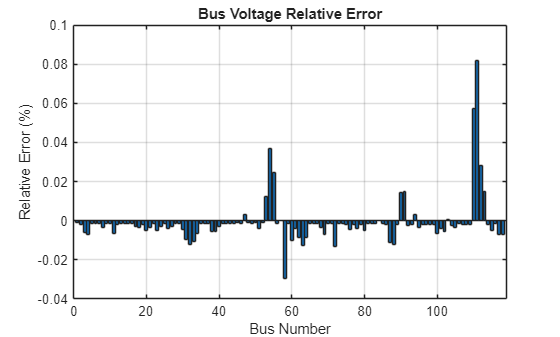

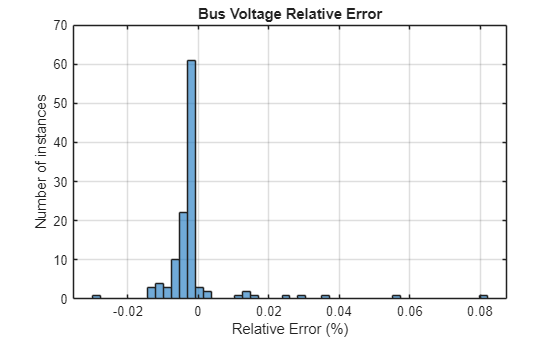

compareVoltage

Plot the frequency response of each synchronous machine - offset the time by 10 seconds so the trip occurs at 1 second on the plot.

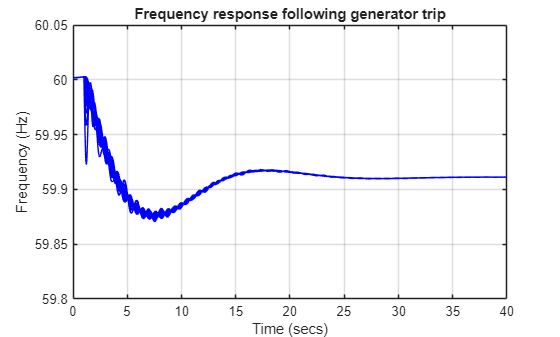

figure,plot(out.w.Time-10,reshape(out.w.Data,54,numel(out.w.Time)),'b'),grid
axis([0 40 59.8 60.05])
title('Frequency response following generator trip')
xlabel('Time (secs)'),ylabel('Frequency (Hz)')

## Subsequent Use of the System Model

Once the steps in this document have been taken, you do not need to rebuild the system. For subsequent simulations, load the appropriate data files and top-level model.

END OF DOCUMENT